# One Dimensional Advection Equation (Tweeks)

## Problem Description (Grid Formation)

And here is the description of the grid used.

clc;
clear all;
%-------Domain Parameter-----%

% Grid Points
global Nx;
Nx = 400;

%--Important Parameters
INFINITE = 10^12;
eta = 10^-6;
error_eta = 10^-9;
CFL = 0.5;

% Dimension of Domain
Lx = 100;

% Domain
global x;
x = linspace(0,Lx,Nx);

% Defining velocity
global x_velocity;

% Space Interval
global h;
h = Lx/Nx;

% Total Time
t_total = 7;

## Initial Condition

And this is the initial condition of the problem. As always, I have used Gaussian Initial Condition.

% Initial Condition (Density)

xc = 20;     % center x
sigma = 5;   % width
rho = 0.1*exp(-((x-xc).^2) / (2*sigma^2) ) + 0.1;

## Velocity Distribution

Here I have set the velocity distribution in the domain

% Initial Condition (Velocity)
%--Function to compute Velocity using Density
function speed = makeSpeed(rho)
    global Nx;
    global x;
    speed = zeros(Nx);
    for i = 1:1:Nx
        speed(i) = 0.1*x(i) + 10;
    end
end

x_velocity = makeSpeed(rho);

## Plots

### Initial Density

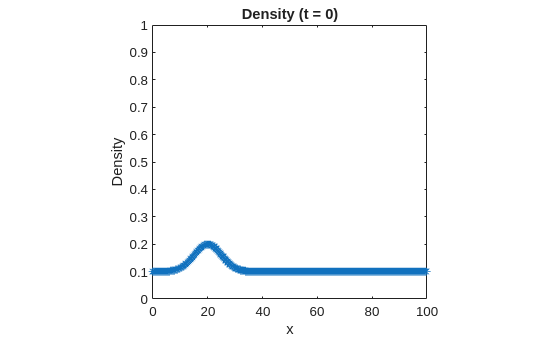

% Plot of Density
figure(1)
plot(x,rho,'*')
title('Density (t = 0)')
xlabel('x')
ylabel('Density')
xlim([0 100])
ylim([0 1])
axis square

### Initial Speed

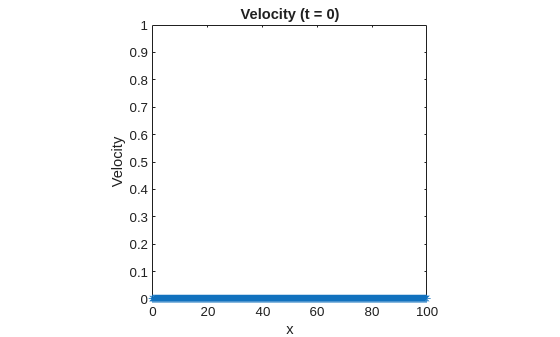

% Plot of Density
figure(2)
plot(x,x_velocity,'*')
title('Velocity (t = 0)')
xlabel('x')
ylabel('Velocity')
xlim([0 100])
ylim([0 1])
axis square;

### Flux Calculation

%-- Function that will calculate the flux depending on the u,v and Density.
function flux = makeFlux(rho)
    global Nx x_velocity;

    % Initialzing Flux
    flux = zeros(Nx);
    for i = 1:1:Nx
        flux(i) = rho(i) * x_velocity(i);
    end 
end

### Main Solver

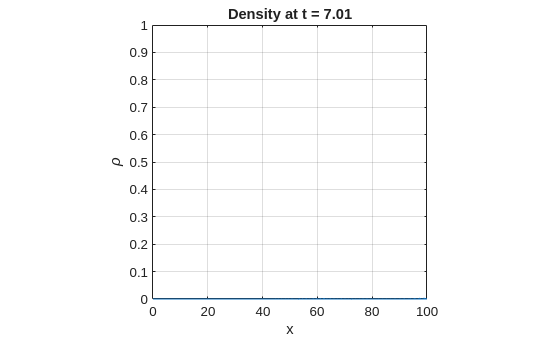

%--Video Capturing--%
video = VideoWriter('problem_2.avi', 'Motion JPEG AVI');
video.FrameRate = 20;
open(video);

%--Preallocating the memory
rho_n = zeros(Nx);
rho_1 = zeros(Nx);
rho_2 = zeros(Nx);
rho_next = zeros(Nx);


%-----------MAIN SOLVER------------%
t = 0; 
step = 0; % For plotting at regular interval

while t< t_total
    % Computing Cost For the density rho
    x_velocity = makeSpeed(rho);

    % Updating the delta_t with proper CFL condition (Wiki Pedia)
    u_max = max(x_velocity(:));
    dt = CFL / ( u_max/h + 1e-12 );

    % -- Making rho_n and RHS of rho_n
    rho_n = rho;
    semi_discritze_form_rho_n = makeRHS(rho_n);


    % ---------- Making the RHO_1 and then RHS of rho_1 ------ %
    for i = 4:1:Nx-2
        rho_1(i) = rho_n(i) + dt * semi_discritze_form_rho_n(i-3);
    end
    % -- Extrapolation (My Intuition)
    rho_1(3) = rho_1(4); rho_1(2) = rho_1(3); rho_1(1) = rho_1(2);  % Right Edge
    rho_1(Nx-1) = rho_1(Nx-2); rho_1(Nx) = rho_1(Nx-1);             % Left Edge
    % -- RHS of discritised form using rho_1
    semi_discritze_form_rho_1 = makeRHS(rho_1);



    %--------- Making the RHO_2 and RHS of RHO_2 ----------%
    for i = 4:1:Nx-2
        rho_2(i) = 3/4 * rho_n(i) + 1/4 * (rho_1(i) + dt * semi_discritze_form_rho_1(i-3));
    end
    % -- Extrapolation (My Intuition)
    rho_2(3) = rho_2(4); rho_2(2) = rho_2(3); rho_2(1) = rho_2(2);  % Right Edge
    rho_2(Nx-1) = rho_2(Nx-2); rho_2(Nx) = rho_2(Nx-1);             % Left Edge

    % -- RHS of discritised form using rho_2
    semi_discritze_form_rho_2 = makeRHS(rho_2);


    %----------Making the rho_next-------------------------%
    
    for i = 4:1:Nx-2
        rho_next(i) = 1/3 * rho_n(i) + 2/3 * (rho_2(i) + dt * semi_discritze_form_rho_2(i-3));
    end    
    % -- Extrapolation (My Intuition)
    rho_next(3) = rho_next(4); rho_next(2) = rho_next(3); rho_next(1) = rho_next(2);    % Left Edge
    rho_next(Nx-1) = rho_next(Nx-2); rho_next(Nx) = rho_next(Nx-1);                     % Right Edge

    step = step + 1;

    % Substituting back the rho value \
    rho = rho_next;

    % Updating the time
    t = t + dt;

    %--Plotting rho
    if mod(step,1) == 0
    
        figure(6);
        plot(x, rho, '-');   % blue line with thickness
        
        ylim([0 1]);
        xlim([0 100]);
        
        title(sprintf('Density at t = %.2f', t));
        xlabel('x');
        ylabel('\rho');
        
        grid on;
        axis square;
        
        drawnow;

        frame = getframe(gcf);
        writeVideo(video, frame);
    
    end
end

close(video);

### To find the expression for L(Rho)

function semi_discrite_form =  makeRHS(rho)
    global Nx x_velocity h;
    semi_discrite_form = zeros(Nx-5);

    %--Flux for the given rho distribution
    flux = makeFlux(rho);

    % Calculating the maximum speed
    alpha_x = max(x_velocity(:));


    % -- Calculating the value of f+ and f- at {i+2,i+1,i,i-1,i-2,i-3} -- %
    fx_negative_whole = zeros(Nx);
    fx_positive_whole = zeros(Nx);

    for i = 1:1:Nx
        fx_positive_whole(i) = 1/2 * (flux(i) + alpha_x*rho(i));
        fx_negative_whole(i) = 1/2 * (flux(i) - alpha_x*rho(i));
    end
    
    % -- Computing the RHS of Semi Discrite form.
    for i = 4:1:Nx-2
        %--X--%
        % fx{+}_[i+1/2,j]
        fx_plus_x_half_forward = stencil( ...
            fx_positive_whole(i-2), ...
            fx_positive_whole(i-1), ...
            fx_positive_whole(i), ...
            fx_positive_whole(i+1), ...
            fx_positive_whole(i+2));
            
        % fx{+}_[i-1/2,j]
        fx_plus_x_half_backward = stencil( ...
            fx_positive_whole(i-3), ...
            fx_positive_whole(i-2), ...
            fx_positive_whole(i-1), ...
            fx_positive_whole(i), ...
            fx_positive_whole(i+1));

        % fx{-}_[i+1/2,j]
        fx_minus_x_half_forward = stencil( ...
            fx_negative_whole(i+2), ...
            fx_negative_whole(i+1), ...
            fx_negative_whole(i), ...
            fx_negative_whole(i-1), ...
            fx_negative_whole(i-2));
            
        % fx{-}_[i-1/2,j]
        fx_minus_x_half_backward = stencil( ...
            fx_negative_whole(i+1), ...
            fx_negative_whole(i), ...
            fx_negative_whole(i-1), ...
            fx_negative_whole(i-2), ...
            fx_negative_whole(i-3));
            
        fx_positive_half = fx_plus_x_half_forward + fx_minus_x_half_forward;
        fx_negative_half = fx_plus_x_half_backward + fx_minus_x_half_backward;

        %--Boundary Condition -- %

        % Left Wall (Flux set to Zero)
        if(i == 4)
            fx_negative_half = 0;
            %fx_positive_half = 0;
        end
        % Right Wall (Flux Set to Zero)

        % Computing RHS of Semi Discritized form
        semi_discrite_form(i-3) = - 1/h * (fx_positive_half - fx_negative_half);    
    end
end


## WENO Advection Stencil

% To compute f half. Order of input matters
function f = stencil(f1,f2,f3,f4,f5)

    eta = 10^-6;

    % Compute S values
    s_1 = ((1/3) * f1) + ((-7/6) * f2) + ((11/6) * f3);
    s_2 = ((-1/6) * f2) + ((5/6) * f3) + ((1/3) * f4);
    s_3 = ((1/3) * f3) + ((5/6) * f4) + ((-1/6) * f5);

    % Compute Beta
    beta_1 = 13/12 * (f1 - 2*f2 + f3)^2 + 1/4 * (f1 - 4*f2 + 3*f3)^2;
    beta_2 = 13/12 * (f2 - 2*f3 + f4)^2 + 1/4 * (f2 - f4)^2;
    beta_3 = 13/12 * (f3 - 2*f4 + f5)^2 + 1/4 * (3*f3 - 4*f4 + f5)^2;

    % Definign Gamma
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;

    % Computing weights bar
    w_1_dash = ( gamma_1 ) ./ ((eta + beta_1)^2);
    w_2_dash = ( gamma_2 ) ./ ((eta + beta_2)^2);
    w_3_dash = ( gamma_3 ) ./ ((eta + beta_3)^2);

    % Computing Weights
    w_1 = ( w_1_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_2 = ( w_2_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_3 = ( w_3_dash ) / (w_1_dash + w_2_dash + w_3_dash);

    % Computing Flux
    f = w_1 * s_1 + w_2 * s_2 + w_3 * s_3;
end